clear all
load("params.mat")

J

J = 	1.0e+03 *

    2.4167
    2.2375
    2.1792


M=[300 200 600]

M =    300   200   600


t=linspace(0,20,100e3);

omega0=[-0.15; 0.1; -0.3]

omega0 =    -0.1500
    0.1000
   -0.3000


A0=eye(3)

A0 =      1     0     0
     0     1     0
     0     0     1



x0=[omega0; reshape(A0,[9 1])]

x0 =    -0.1500
    0.1000
   -0.3000
    1.0000
         0
         0
         0
    1.0000
         0
         0


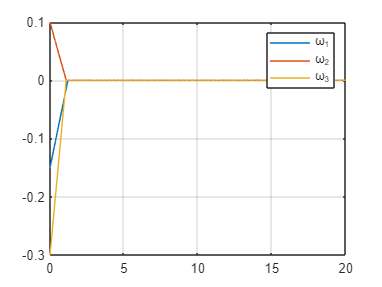



[t,y]= ode45(@(t,x) next(x(1:3),reshape(x(4:end),[3 3]),J,M),t,x0 );
w=y(:,1:3);
a=y(:,4:end);
figure
plot(t,w)
grid on
legend("\omega_1","\omega_2","\omega_3")

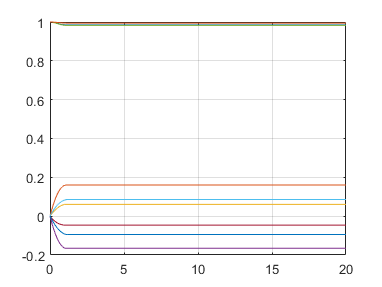


figure
plot(t,a)
grid on


syms a [3,3] real
syms da [3,3] real
syms omega_E [3,1] real

a

$$a = \left(\begin{array}{ccc} a_{1,1} & a_{1,2} & a_{1,3}\\ a_{2,1} & a_{2,2} & a_{2,3}\\ a_{3,1} & a_{3,2} & a_{3,3} \end{array}\right)$$

Omega = [
    0 -omega_E3 omega_E2
    omega_E3 0 -omega_E1
    -omega_E2 omega_E1 0
    ]

$$Omega = \left(\begin{array}{ccc} 0 & -\omega_{\mathrm{E3}} & \omega_{\mathrm{E2}}\\ \omega_{\mathrm{E3}} & 0 & -\omega_{\mathrm{E1}}\\ -\omega_{\mathrm{E2}} & \omega_{\mathrm{E1}} & 0 \end{array}\right)$$


dA= -a*Omega

$$dA = \left(\begin{array}{ccc} a_{1,3}\,\omega_{\mathrm{E2}}-a_{1,2}\,\omega_{\mathrm{E3}} & a_{1,1}\,\omega_{\mathrm{E3}}-a_{1,3}\,\omega_{\mathrm{E1}} & a_{1,2}\,\omega_{\mathrm{E1}}-a_{1,1}\,\omega_{\mathrm{E2}}\\ a_{2,3}\,\omega_{\mathrm{E2}}-a_{2,2}\,\omega_{\mathrm{E3}} & a_{2,1}\,\omega_{\mathrm{E3}}-a_{2,3}\,\omega_{\mathrm{E1}} & a_{2,2}\,\omega_{\mathrm{E1}}-a_{2,1}\,\omega_{\mathrm{E2}}\\ a_{3,3}\,\omega_{\mathrm{E2}}-a_{3,2}\,\omega_{\mathrm{E3}} & a_{3,1}\,\omega_{\mathrm{E3}}-a_{3,3}\,\omega_{\mathrm{E1}} & a_{3,2}\,\omega_{\mathrm{E1}}-a_{3,1}\,\omega_{\mathrm{E2}} \end{array}\right)$$

Уравнения Эйлера и Пуассона

function y=next(omega,A,J,M)

dw=zeros(3,1);

dw(1)=( (J(2)-J(3)) * omega(2) * omega(3) - M(1) * sign(omega(1)) ) / J(1);
dw(2)=( (J(3)-J(1)) * omega(3) * omega(1) - M(2) * sign(omega(2)) ) / J(2);
dw(3)=( (J(1)-J(2)) * omega(1) * omega(2) - M(3) * sign(omega(3)) ) / J(3);

Omega = [
    0 -omega(3) omega(2)
    omega(3) 0 -omega(1)
    -omega(2) omega(1) 0
    ];

dA=-A*Omega;

y=[dw;reshape(dA,[9 1])];
end